# A template for running sMLSM

## Loading brain data

### Step 1: Place all your lesion maps (or nifti maps containing other types of data) in a folder. Define this folder below as well as its parent:

bd = 'C:\Users\alext\Documents\MATLAB\StabilitySelection-main'; % parent, or base directory. We use this to determine where to write files, and some other general functions.
dataFolder = 'C:\Users\alext\Documents\MATLAB\StabilitySelection-main\Example'; % directory containing brain data

% Let's also make sure this package is in our working directory before we
% proceed
appPath = which('stabSel.m');
addpath(genpath(fileparts(appPath)));

### Step 2: Call loadBrain and (probably) hit cancel when asked for a mask

You can supply a mask if you want (a single nifti), which will constrain the voxels we look at.

Note, loadBrain uses a series of different functions to try to load your data (see documentation). So, for example, if you have load_nifti.m lying around, or spm installed, it will draw on that. However, you don't need any *external* packages and it can just use the matlab imaging toolbox if you installed it with matlab.

[fileNames,X,bid,initSz] = brainLoad(dataFolder,[]);

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
No loadable mask supplied Proceeding without the mask...if this is not expected behavior please make sure spm_read_vols or load_nifti or niftiread is in your path
Working on file 1 of 1
File is: lesion
Could not load in file! C:\Users\alext\Documents\MATLAB\StabilitySelection-main\Example\lesion


### Step 3: Load in your behavioral data (assuming it is an excel file or a csv)

beh = readtable([bd filesep 'Behavior.csv']); % readtable is an internal matlab function

#### Step 4: Map behavioral data onto brain data

[c,ia,ib] = intersect(beh.RegistryCode,extractBefore(fileNames','.nii.gz'),'stable'); % include extractBefore extension beacause behavioral data doesn't include extension after subID
if length(c) == length(fileNames) % this checks whether all files were mapped or if there are some missing (e.g., missing brain data when behavioral exists or vice-versa)
    disp('Sanity checking files all mapped: yes')
else
    disp('Sanity checking files all mapped: NO! check data')
end

Sanity checking files all mapped: yes


if isequal(ia,ib) % first variable given to intersect indexed by ia will equal second variable passed on to intersect indexed by ib. So if they are not equal and we used 'stable' (do not reorder the first variable we passed in), then we need to reindex both variables using ia and ib
    disp('Actually...we do not need to reindex, you can skip and continue on')
else
    disp('Reindex...run beh = beh(ia,:); and to be safe you can also run X = X(ib,:);') % you can just run those lines if you trigger this else statement
end

Actually...we do not need to reindex, you can skip and continue on


## Organize your data

### We'll use the X (brain data), y (response variable) and z (lesion size) nomenclature from the Tutorial3 code.

y = beh.Behavior; % response variable we will predict, but you can replace .Behavior with whichever column you are analyzing
z = sum(X)'; % estimate lesion size (this is an approximation and will work better if in 1mm space, you should consider doing something more sophisticated if you can). Note, you may not need lesion size at all.
X = X'; % we'll also transpose X for conventience-- code generally assumes rows are subjects and columns are features

### Bin your voxels by regions of interest in an atlas or nifti file of your choice. This is an example using one atlas. 

#### brainLoad can be used to load in a single file--you will have to hit cancel when prompted to provide a mask

Note: make sure your atlas has the same shape as your brain data

Xorig = X; % backup X
[~,schVol,~,schSz] = brainLoad('C:\Users\alext\Downloads\MNI_Atlas\Schaefer2018_1000Parcels_7Networks_order_FSLMNI152_1mm.nii.gz',[]); % again, hit cancel for mask...

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
No loadable mask supplied Proceeding without the mask...if this is not expected behavior please make sure spm_read_vols or load_nifti or niftiread is in your path
Working on file 1 of 1
File is: Schaefer2018_1000Parcels_7Networks_order_FSLMNI152_1mm.nii.gz


#### This roiBin function gets the mean of your brain data within each ROI. If your brain data is binary lesion masks, then this amounts to getting the proportion of the ROI that is damaged.

[X, roiIds, vIds] = roiBin(Xorig,schVol);

## Optional: Combining atlases together

Here is how you might achieve combining atlases together--simply run the same code as above and concatenate. You may also want to track which roi index comes from which file or atlas using a cell array as shown below.

% since we have two files, let's keep track of the file associated with each ROI index or intensity value that we are storing...
roiFiles = repmat({'schaeffer'},length(roiIds),1);

% now get the data for aseg
[~, asegVol, ~, asegSz] = brainLoad('C:\Users\alext\Downloads\MNI_Atlas\aseg.nii',[]);
[X2, roiIds2, vIds2] = roiBin(Xorig,schVol); % get rois
roiFiles2 = repmat({'aseg'},length(roiIds2),1); % since we have two files, let's keep track of the file associated with each ROI index or intensity value that we are storing...

% Concatenate everything
X = [X X2]; 
roiIds = [roiIds; roiIds2];
roiFiles = [roiFiles; roiFiles2];
vIds = [vIds vIds];

## You may want to remove ROIs that are underrepresented using something like this

This is just a starting off point, you should carefully think about thresholding data and the consequences of this.

s = sum(X >= 0.1); % count for each roi of the # of subjects that had > 10% of the ROI damaged
rid = find(s == 0); % rois where no subject had > 10% of the ROI damaged
X(:,rid) = [];
roiIds(rid) = [];
roiFiles(rid) = [];
vIds(rid) = [];

## A simple LSM example illustrating how to save ROI results from LSM or sMLSM

% regress lesion size out of the behavior for univariate analyses. In
% multivaraite analyses, we include lesion size in the models themselves wherever possible.
% mdl = fitlm(z,y,'RobustOpts','on'); % Up to you on whether to include...regresses lesion size out of behavior
% yRes = mdl.Residuals.Standardized;
yRes = y; % comment this out and uncomment the lines above to regress out lesion size from the data

% we will do a permutation analysis with a 2-sample t-test
numPermutations = 10;  % you should use 10k, this is just for testing

% Preallocate the p-values array for permutations
permuted_p = zeros(size(X,2), numPermutations);

% Loop over each feature
for i = 1:size(X,2)
   disp(['Working on feature ' num2str(i) ' of ' num2str(size(X,2))]);

    % get lesioned and nonlesioned participants
    id1 = find(X(:,i) >= 0.1); % We assume if less than 10% of the ROI is damaged, that means it's not actually dysfunctional
    id2 = find(X(:,i) < 0.1);
    
    % count number of patients in each group
    le(i,1) = length(id1);
    le(i,2) = length(id2);
    
    % Check for adequate sample sizes to test else effect is insignificant
    if le(i,1) >= 10 && le(i,2) >= 10
        % perform t-test
        [h,p(i,1),~,stats] = ttest2(yRes(id1), yRes(id2),"Tail","left");
        t(i,1) = stats.tstat;

        % Permutation test starts here
        for j = 1:numPermutations
            % Permute the response variable
            permutedLabels = yRes(randperm(length(yRes)));
            
            % Recalculate tests for the permuted data
            [~,permuted_p(i,j),~,stats] = ttest2(permutedLabels(id1), permutedLabels(id2),"Tail","left");
            permuted_t(i,j) = stats.tstat;
        end
        
        % Calculate the empirical p-values for both tests
        p_value_perm(i,1) = sum(permuted_p(i,:) <= p(i,1))./numPermutations;
        t_value_perm(i,1) = sum(permuted_t(i,:) <= t(i,1)) / numPermutations;
    else
        p(i,1) = NaN;
        t(i,1) = NaN;
        p_value_perm(i,1) = NaN; 
        t_value_perm(i,1) = NaN; 
    end
end

Working on feature 1 of 933
Working on feature 2 of 933
Working on feature 3 of 933
Working on feature 4 of 933
Working on feature 5 of 933
Working on feature 6 of 933
Working on feature 7 of 933
Working on feature 8 of 933
Working on feature 9 of 933
Working on feature 10 of 933
Working on feature 11 of 933
Working on feature 12 of 933
Working on feature 13 of 933
Working on feature 14 of 933
Working on feature 15 of 933
Working on feature 16 of 933
Working on feature 17 of 933
Working on feature 18 of 933
Working on feature 19 of 933
Working on feature 20 of 933
Working on feature 21 of 933
Working on feature 22 of 933
Working on feature 23 of 933
Working on feature 24 of 933
Working on feature 25 of 933
Working on feature 26 of 933
Working on feature 27 of 933
Working on feature 28 of 933
Working on feature 29 of 933
Working on feature 30 of 933
Working on feature 31 of 933
Working on feature 32 of 933
Working on feature 33 of 933
Working on feature 34 of 933
Working on feature 35 o

Save out the results...example to show you how you can save out nifti files. To save out a different variable from above, you can just replace t from xtmp = t(fid); with whatever variable you are interested in.

info = niftiinfo([dataFolder filesep fileNames{3}]); % gets header for the 3rd lesion file we previously loaded as a template for writing out new files

fs = unique(roiFiles); % get unique files we concatenated
for i = 1:length(fs) % loop over these files
    tout = zeros(initSz); % set up an output map we will write to
    fid = find(ismember(roiFiles,fs{i})); % find all rois in the i map by getting all feature columns that match the file i
    xtmp = t(fid); % here we get t-maps for this file i
    roiIdsTmp = roiIds(fid); % roi indices for the i file
    vIdsTmp = vIds(fid); % voxel indices for the i file
    for j = 1:length(roiIdsTmp) % jth roi in file i
        vid = vIdsTmp{j}; % all voxel indices for jth roi
        tout(vIdsTmp{j}) = xtmp(j); % the value we got from analysis for the the jth roi
    end
    niftiwrite(single(tout),[bd filesep 'LSM_tvalues.nii.gz'],info) % write file i
end

## Run sMLSM

### Step 1: Create a repeated cross-validation scheme stratified by lesion size. 

#### I set this to 4-fold CV to more quickly run through the code and make sure it works, but you should really aim for something like 8-fold CV.

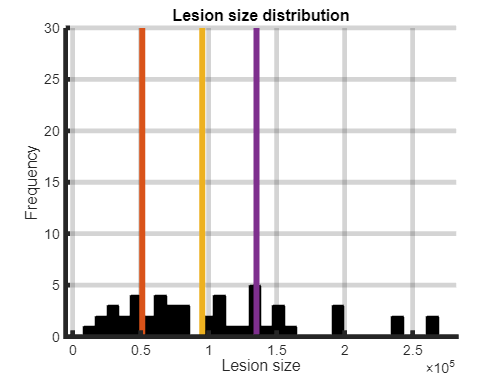

% Create lesion size quantiles from our data
clear c
q = quantile(z,[0.25 0.5 0.75]); 
cat = zeros(1,length(z));
cat(z <= q(1)) = 1; %1st lesion size category (<= 1st quartile)
cat(z > q(1) & z <= q(2)) = 2; % 2nd lesion size category (> 1st quartile and <= median)
cat(z > q(2) & z <= q(3)) = 3; % 3rd lesion size category (> median and <= 3rd quartile)
cat(z > q(3)) = 4; % 4th lesion size category (> 3rd quartile)

for j = 1:10 % we will make 11 random partitions stratified by our lesion quartiles...
    c{j} = cvpartition(cat,"KFold",4,"Stratify",true);
end
save([bd filesep 'cv_scheme.mat'],'cat','c')

% this is a simple plot of the quartiles...you can see each group is about
% the same in size
figure; histogram(z,30,'FaceAlpha',1,'FaceColor',[0 0 0]);
hold on
plot([q(1) q(1)],[0 30],'LineWidth',5);
plot([q(2) q(2)],[0 30],'LineWidth',5);
plot([q(3) q(3)],[0 30],'LineWidth',5);
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
title('Lesion size distribution')
ylabel('Frequency')
xlabel('Lesion size')

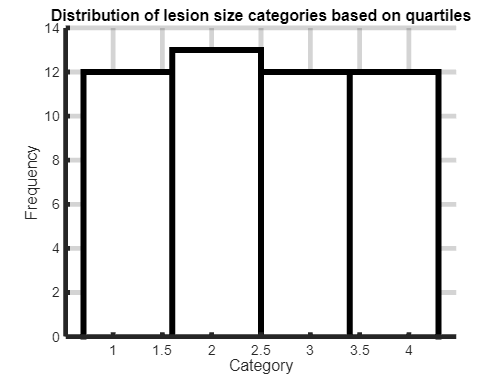

figure; histogram(cat,4,'FaceAlpha',1,'FaceColor',[1 1 1],'LineWidth',5);
title('Distribution of lesion size categories based on quartiles')
set(gcf,'color','w');set(gca,'FontSize',12); set(gca,'LineWidth',4); box off; grid on; set(gca,'GridAlpha',0.2);
ylabel('Frequency')
xlabel('Category')

### Step 2: Run Stability selection for each outer fold in each repeat of CV. Inner folds will be created later. 

Note, we are subsampling below but you could use bootstrapping (with or without complementary pairs). The number of false positives we use to establish the stable set is an arbitrary 3. This is fine, as we will actually run the next analysis over a set of these values since we can change them after we do an initial run of stabSel. For the number of features to retain in each subsample, we'll just take 15%. This choice is arbitrary and proportional to how consistent the feature ends up having to be in order to qualify as being stable. So if you select most of your features to keep in each subsample, the threshold for a stable feature will be very high. That being said, I don't think this variable is as arbitrary as suggested in a lot of the stability selection work. I recommend being more rather than less selective where possible as diversity in selected features should lead to a more robust solution.

A final few points. First, I ran the below for just 1 repeat from the CV scheme for brevity but you really should run multiple repeats to get a better sense of how partitioning noise influences your estimate of model generalizability.

for r = 1%:length(c)
    for i = 1:c{r}.NumTestSets 
        disp(['Working on outer fold:' num2str(i)])
        [fkRaw{r}{i},~,probRaw{r}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{r}{i},~,~,~] = stabSel(X(training(c{r},i),:),y(training(c{r},i)),'selAlgo','en',...
            'samType','subsample','rep',500,'compPars',false,'numFalsePos',3,'maxVars',round(size(X,2)*0.15),'keepScores',false,...
            'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
    end
    try
        save([bd filesep 'stabSel_results.mat']);
    catch
        save([bd filesep 'stabSel_results.mat'],'-v7.3');
    end
end

Working on outer fold:1


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

Working on outer fold:2


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

Working on outer fold:3


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

Working on outer fold:4


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 500
Working on subsample 2 of 500
Working on subsample 3 of 500
Working on subsample 4 of 500
Working on subsample 5 of 500
Working on subsample 6 of 500
Working on subsample 7 of 500
Working on subsample 8 of 500
Working on subsample 9 of 500
Working on subsample 10 of 500
Working on subsample 11 of 500
Working on subsample 12 of 500
Working on subsample 13 of 500
Working on subsample 14 of 500
Working on subsample 15 of 500
Working on subsample 16 of 500
Working on subsample 17 of 500
Working on subsample 18 of 500
Working on subsample 19 of 500
Working on subsample 20 of 500
Working on subsample 21 of 500
Working on subsample 22 of 500
Working on subsample 23 of 500
Working on subsample 24 of 500
Working on subsample 25 of 500
Working on subsample 26 of 500
Working on subsample 27 of 500
Working on subsample 28 of 500
Working on subsample 29 of 500
Working on subsample 30 of 500
Working on subsample

### Step 3: Run sMLSM using the stabSel features above

You may be wondering why we are running this separately from stabSel. This is just a personal preference since the folds are preallocated. In case a step of the analysis fails, this can help to make sure you don't lose as much work. 

It is also worth mentioning that the inner folds were *not* preallocated during our calls to cvpartition. This is strategic--curently, matlab's machine learning toolbox does not let you repartition folds if you pass in your own cvpartition object. You can decide if this is the right choice for you. There are certainly drawbacks to this approach if you are comparing models, but repartitioning during hyperparameter tuning is, I believe, worth it as it helps account for partitioning noise during tuning.

Also, you may want to increase the number of inner folds and/or evaluations. Note, you can also set UseParallel to true to speed things up if you have the parallel toolbox. Finally, consider re-evaluating the specific number of false positives we are testing depending on your results (e.g., if you get a lot of empty stable sets).

tot = 30; % this is the max number of false positives we will test: 1...tot
for r = 1:length(fkRaw) % loop over repeats of CV...
    disp(['Working on repeat:' num2str(r) ' of ' num2str(length(fkRaw))])
    for n = 1:tot % loop over sequence of false positives
        for i = 1:length(fkRaw{r}) % test set

            % first define your new stable set...
            fkfin{i}{r}{n} = recompStableFeats(probRaw{r}{i},empMaxVarsRaw{r}{i},n);

            % define hyperparameters for sMLSM with SVM
            hype = hyperparameters('fitrsvm',[X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to train the SVM on stable features plus lesion
            % size (sMLSM model). You can increase the number of
            % evaluations here for bayesian optimization and this
            % should improve model performance a tiny bit. Note, hype options override other arguments (e.g., KernelFunction,linear)

            bmdlAF{i,r,n} = fitrsvm([X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                'expected-improvement-plus','Kfold',4,'UseParallel',false,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
            % Get sMLSM model predictions
            yhatAF(test(c{r},i),r,n) = predict(bmdlAF{i,r,n},[X(test(c{r},i),fkfin{i}{r}{n}) z(test(c{r},i))]);
        end

        if n == 1
            guessLV(test(c{r},i),r) = mean(y(training(c{r},i)));
        end

        % compute various performance measures for each sMLSM model
        [AF_corr(r,n),AF_corrp(r,n)] = corr(yhatAF(:,r,n),y);
        AF_mae(r,n) = mean(abs(y-yhatAF(:,r,n)));
        AF_mase(r,n) = AF_mae(r,n) ./ mean(abs(y-guessLV(:,r)));
        AF_ap(r,n) = (1-AF_mase(r,n))*100;
    end
    try
        save([bd filesep 'sMLSM_results.mat']);
    catch
        save([bd filesep 'sMLSM_results.mat'],'-v7.3');
    end
end

Working on repeat:1 of 1


### Step 4: The code above runs sMLSM over *all* number of false positive settings between 1 and 30. You can see how the model does if you select a specific stable set below, but later we will come up with a single *tuned *model by selecting which false positive setting was optimal for each fold.

#### Note, quickScatter.m is from another package: https://github.com/alexteghipco/Correlogram

% get mean and SEM for performance measures
AF_corr_m = mean(AF_corr);
AF_ap_m = mean(AF_ap);

AF_corr_sem = std(AF_corr)./sqrt(length(AF_corr));
AF_ap_sem = std(AF_ap)./sqrt(length(AF_corr));

% Now compute stable set sizes, sFDR
for a = 1:length(fkRaw)
    disp(['Working on repeat: ' num2str(a) ' of ' num2str(length(fkRaw))])
    for n = 1:30
        for i = 1:length(fkRaw{a}) % test set
            nfk(a,i,n) = length(fkfin{i}{a}{n});
            ep(a,i,n) = n./nfk(a,i,n);
        end
    end
end

Working on repeat: 1 of 1


pfer_m = squeeze(mean(mean(ep,2,'omitnan'),1,'omitnan'))'; % pfer is really sfdr (proportion of stable set that may be a false positive). Here we take the mean.
pfer_sem = squeeze(std(mean(ep,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1)); % Here we take the SEM.
nfk_sem = squeeze(std(mean(nfk,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1)); % This is SEM for stable set size

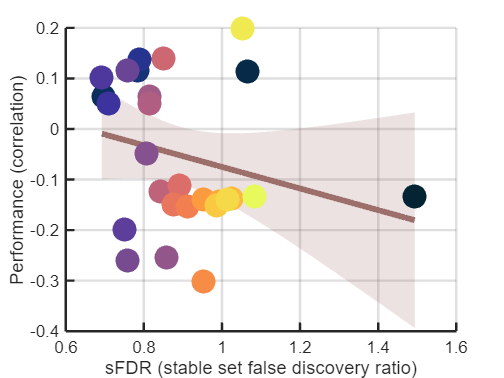

addpath(genpath('C:\Users\alext\Downloads\Correlogram-main')) % you will have to add the correlogram package to your path at this point

% if you only ran one repeat like I did above for illustrative reasons, you
% won't be able to have SEM bars in your scatter plot so we use this try
% statement
try
    [parts] = quickScatter(AF_corr_m,pfer_m,'perfectY',false,'useWholeMap',true,'err',[AF_corr_sem; pfer_sem]','markerAlpha',1,'newFig',true);
catch
    % Also, we need to remove empty stable sets, which should show up as
    % Infs in pfer_m. You may need to do something like this for the try
    % portion of this code snippet as well if you get errors during
    % plotting.
    id = find(isinf(pfer_m));
    pfer_m(id) = [];
    AF_corr(id) = [];
    AF_ap(id) = [];
    [parts] = quickScatter(AF_corr,pfer_m,'perfectY',false,'useWholeMap',true,'markerAlpha',1,'newFig',true);
end
parts.annot.Visible = 'off';set(gca,'FontSize',14)
box off;
xlabel('sFDR (stable set false discovery ratio)')
ylabel('Performance (correlation)')

% Accuracy percent is an arguably better measure--closer to MAE (percent by
% which we improve over a naive guessing model based on the mean of the
% training data). Here we plot this instead of correlation.
try
    [parts] = quickScatter(AF_ap_m,pfer_m,'perfectY',false,'useWholeMap',true,'err',[AF_corr_sem; pfer_sem]','markerAlpha',1,'newFig',true);
catch
    % Also, we need to remove empty stable
    % sets, which should show up as Infs in pfer_m in this case. You may
    % need to do something like this for the try portion as well if you get
    % errors during plotting.
    [parts] = quickScatter(AF_ap,pfer_m,'perfectY',false,'useWholeMap',true,'markerAlpha',1,'newFig',true);
end
parts.annot.Visible = 'off';set(gca,'FontSize',14)
box off;
xlabel('sFDR (stable set false discovery ratio)')
ylabel('Performance (accuracy percent)')

## For getting a tuned model where we select a *single* false positive setting based on out of sample error during tuning

In larger sample sizes, we found that linearly weighting the loss to favor lower sFDR did not work as well, so below we have removed this but to reverse it just replace this line:

%moderrw = moderr;

With this line:

%moderrw = moderr .* (1 + 0.002 .* [1:length(moderr)]');

And here is the code snippet for generating a model where we tune the sMLSM model to select a single number of false positives. Note, we are effectively doing this in the inner loop. In other words, the inner CV scheme is repeated for every false positive setting between 1 and 30 in increments of 1, then we select whichever inner CV model was best for dete

tot = 30;
for r = 1:length(fkRaw) % repeats
    disp(['Working on repeat ' num2str(r) ' of ' num2str(length(fkRaw))])
    for i = 1:length(fkRaw{r}) % test set
        % for i, which n wins?'
        for n = 1:tot % extract model loss
            moderr(n,1) = bmdlAF{i,r,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
            ep(i,r,n) = n./length(fkfin{i}{r}{n});
            epc(i,r,n) = n./size(X,2);
        end
        moderrw = moderr; % linearly weight the loss slightly to favor lower sFDR by favoring a smaller number of false positive here.
        [mv,nfpWinner(i,r)] = min(moderrw);
        epWinner(i,r) = nfpWinner(i,r)./length(fkfin{i}{r}{nfpWinner(i,r)});
        epcWinner(i,r) = nfpWinner(i,r)./size(X,2);
        yhatAFT(test(c{r},i),r) = predict(bmdlAF{i,r,nfpWinner(i,r)},[X(test(c{r},i),fkfin{i}{r}{nfpWinner(i,r)}) z(test(c{r},i))]);
    end
    [AF_corrT(r,1),AF_corrpT(r,1)] = corr(yhatAFT(:,r),y);
    AF_maeT(r,1) = mean(abs(y-yhatAFT(:,r)));
    AF_maseT(r,1) = AF_maeT(r,1) ./ mean(abs(y-guessLV(:,r)));
    AF_apT(r,1) = (1-AF_maseT(r,1))*100;
end

Working on repeat 1 of 1


AF_corrT_m = mean(AF_corrT);
AF_apT_m = mean(AF_apT);

AF_corrT_sem = std(AF_corrT)./length(AF_corrT);
AF_apT_sem = std(AF_apT)./length(AF_corrT);

This is just a summary of the tuned model's performance

disp(['Tuned model correlation is: ' num2str(AF_corrT)])
disp(['Tuned model accuracy percent is: ' num2str(AF_apT_m)])